### Extracting the SAM-recognized trees

By loading the output labeled matrix from the SAM classification and using it as a mask for the original hyperspectral image

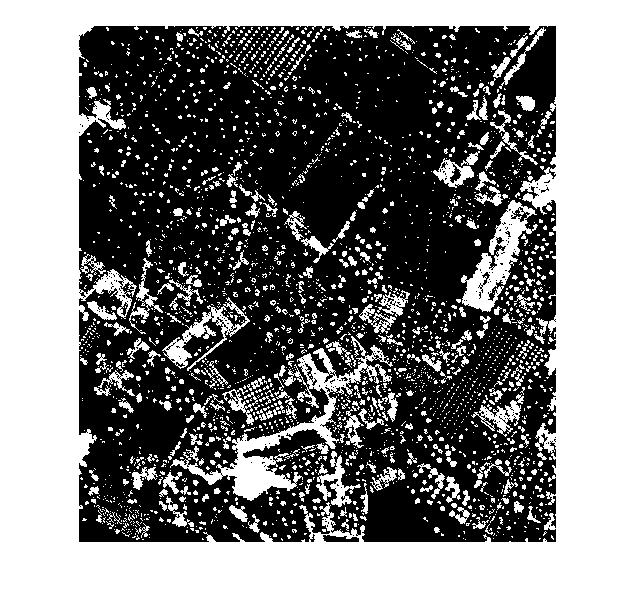

load("testGT.mat")
load("wavelengths.mat")
hcube = hypercube("CROP1_47.tiff",wavelength);
[rows, cols, ~] = size(hcube.DataCube);
% Masquerade taking all the pixels with label 2 (=Tree)
tree_mask = reshape(classMap==2, [rows, cols]);
figure
imshow(tree_mask,[])

sCube=size(hcube.DataCube);
tree_points=reshape(hcube.DataCube,[],sCube(3));
tree_points(tree_mask,:)=NaN;
tree_points=reshape(tree_points,sCube);

Out of memory.

Related documentation